clear;clc;

# **一、火星着陆器-火星轨道器通信链路**  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%条件设置%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_M=400;% 轨道高度，单位：km
freq=400;
lambda=(3e8/1e6)./freq%波长，单位：m

lambda = 0.7500

theta1=10;%天线仰角，单位：°
T=210;%火星温度，单位：K
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算火星自由空间损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
L_M_f=32.442+20*log10(d_M)+20*log10(freq)

L_M_f = 136.5244

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算火星大气损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%由于吸收系数在UHF频段下波动很小，近似地取其上限
H_M_o=11.1;%单位：km
n_E_air=2.7*1e25/(6.02214129*1e23);%空气的分子数密度，单位：分子/m^3
n_E_o=n_E_air*0.2095;%氧气的分子数密度，单位：分子/m^3
alpha_o=0.007;%氧气的吸收系数
n_E_w=n_E_air*0.0025;%水蒸气的分子数密度，单位：分子/m^3
alpha_w=0.002;%水蒸气的吸收系数
A_M_gas=H_M_o*((1/18733).*alpha_o+(1/969).*alpha_w)

A_M_gas = 2.7058e-05

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算云雾损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
M=0.5;%单位：g/m^3
L_c=1;%单位：km
K1=getK1(freq/1000,T);
A_M_g=(L_c.*K1*M)/(sin(theta1*pi/180))

A_M_g = 1.7854e-04

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算火星沙尘损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
e_d_real=5.23;
e_d_imag=0.26;
N_T=3e7;
r_av=10e-6;%单位：m
H_M_dust=10;%单位：km
A_M_dust=H_M_dust*N_T*(r_av)^3*(1.029e6*e_d_imag)/(e_d_imag+(e_d_real+2)^2);
A_M_dust=A_M_dust./lambda

A_M_dust = 0.0020

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算总损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_M=A_M_gas+A_M_g+A_M_dust+L_M_f ;%单位：dB
disp('火星着陆器-火星轨道器通信链路总损耗为（dB）：');disp(A_M);

火星着陆器-火星轨道器通信链路总损耗为（dB）：
  136.5266



# **三、火星轨道器-地球站通信链路段分析**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%条件设置%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_E=[0.6,1,2,3,4];
d_E=1e8*d_E;% 轨道高度，单位：km
freq=8000;% 频率，单位：MHz
lambda=(3e8/1e6)./freq % 波长，单位：m

lambda = 0.0375

theta2=41.76;% 天线仰角，单位：°
h_S=0.043;% 单位：km
T=288;% 温度，单位：K
rho_w = 0.25;% 水蒸汽密度(g/m^3)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算地球自由空间损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
L_E_f=zeros(length(freq),length(d_E));
for i=1:length(freq)
    for j=1:length(d_E)
        L_E_f(i,j)=32.4+20*log10(d_E(j))+20*log10(freq(i));
    end
end
L_E_f

L_E_f =   266.0248  270.4618  276.4824  280.0042  282.5030


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算地球大气降雨损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%以北京为例
R = 42; %降雨率
phi = 39.54;    %纬度
[k, partial] = getKP(freq/1000, theta2);
f=freq/1000;
gamma_R = k.*R.^partial;
h_phi = (5-0.075*(phi-23))*(phi>23)+5*(phi<=23&&phi>=-21)+...
    (5+0.1*(phi+21)).*(phi<-21&&phi>=-71);
h_R = h_phi+0.36;   %降雨高度
L_S = (h_R-h_S)./sin(theta2*pi/180);    %倾斜路径长度
L_G = L_S*cos(theta2*pi/180);   %倾斜路径的水平投影
r = 1./(1+0.78*sqrt(L_G*gamma_R./f)-0.38*(1-exp(-2*L_G)));    %衰减水平缩减因子
chi = (abs(phi)<36)*(36-abs(phi))*pi/180;
L_R = ( atan((h_R-h_S)/L_G./r)>0 ).*(L_G.*r/cos(theta2*pi/180))+...
        (atan((h_R-h_S)/L_G./r)<=0).*((h_R-h_S)/sin(theta2*pi/180));
v_pre = (1-exp(-theta2*pi/180/(1+chi)))*sqrt(L_R.*gamma_R)./f.^2;
v = 1./(1+sqrt(sin(theta2*pi/180))*(31*v_pre-0.45));    %垂直修正因子
L_E = L_R.*v;    %等效路径长度
A_E_p = gamma_R.*L_E  %雨衰量

A_E_p = 3.6258

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算地球大气吸收损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_E_gas = getA_E_g(freq/1000,h_S,rho_w,theta2);
A_E_gas=real(A_E_gas(1,:))

A_E_gas = 0.0598

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算地球云雾损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
M = 0.25;   %单位：g/m^3
L_c = 1;    %单位：km
K1 = getK1(freq/1000,T);
A_E_g = (L_c.*K1*M)/(sin(theta2*pi/180))

A_E_g = 0.0145

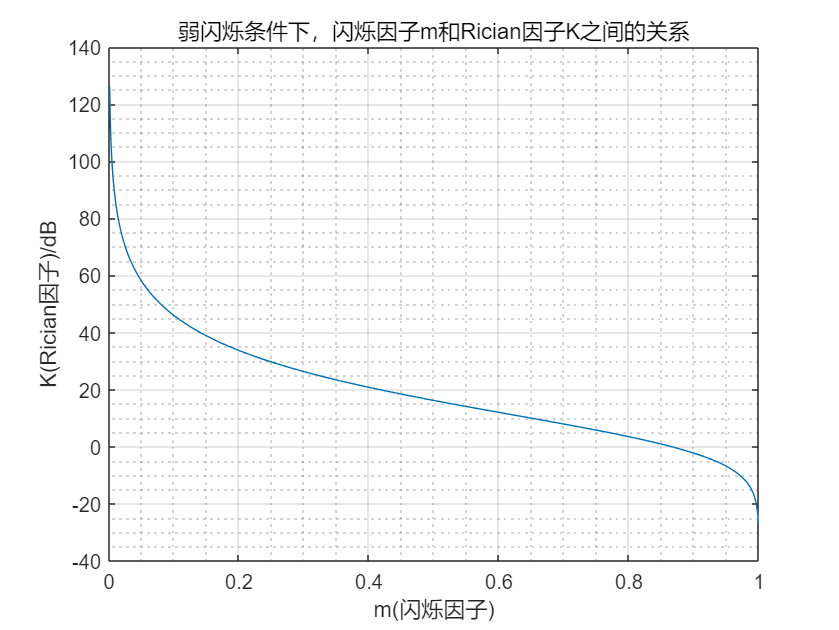

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算太阳闪烁损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%闪烁因子和Rician参数的关系
m = 0:0.001:1;    %闪烁因子，此时弱闪烁
K = sqrt(1-m.^2)./(1-sqrt(1-m.^2));    %莱斯因子
figure();
plot(m, 20*log10(K));
title('弱闪烁条件下，闪烁因子m和Rician因子K之间的关系');
xlabel('m(闪烁因子)');
ylabel('K(Rician因子)/dB');
grid on; grid minor;

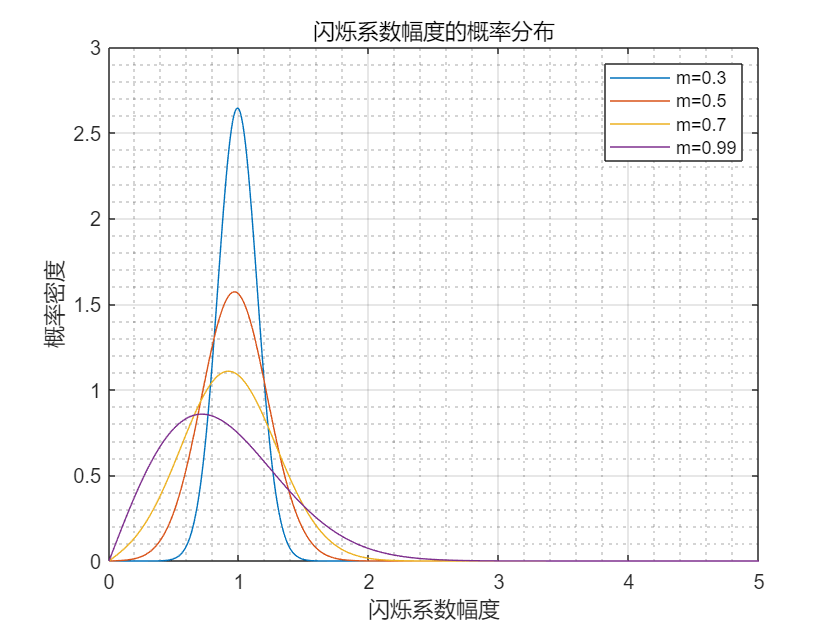

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%不同闪烁因子下，闪烁系数幅度的概率分布
m = [0.3, 0.5, 0.7, 0.99];    %闪烁因子，此时弱闪烁
K = sqrt(1-m.^2)./(1-sqrt(1-m.^2));    %莱斯因子
sigma_nsc = sqrt(1./(K+1));
r = 0:0.01:5;  %闪烁系数的幅度
p_rice = zeros(length(m), length(r));
for i=1:length(m)
   p_rice(i,:) = 2*r/sigma_nsc(i)^2.*exp(-r.^2/sigma_nsc(i)^2-K(i)).*...
       besseli(0, 2*r*sqrt(K(i)/sigma_nsc(i)^2)); 
end
figure();
plot(r, p_rice);
title('闪烁系数幅度的概率分布');
xlabel('闪烁系数幅度');
ylabel('概率密度');
grid on; grid minor;
legend('m=0.3', 'm=0.5', 'm=0.7', 'm=0.99');

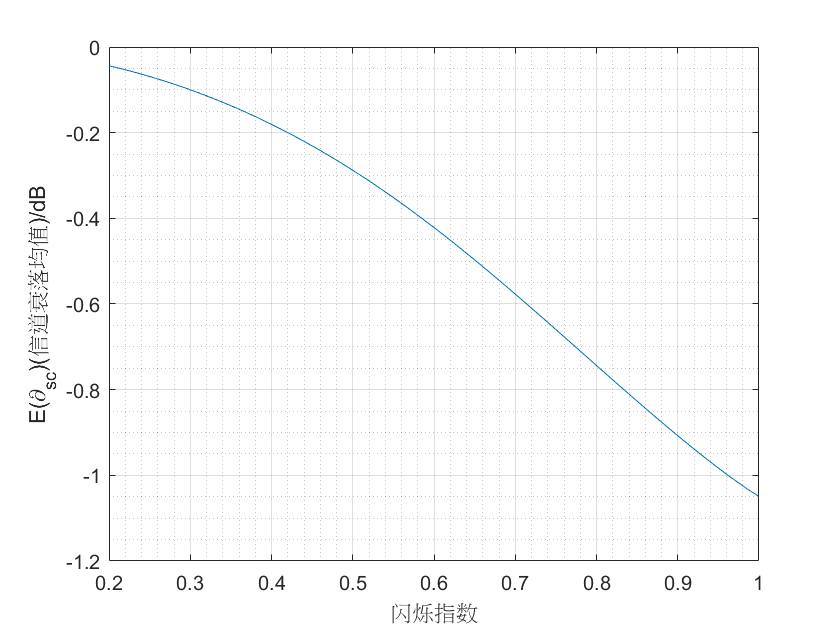

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%闪烁因子和Rician参数的关系
m = 0.2:0.001:0.999;    %闪烁指数，此时弱闪烁
K = sqrt(1-m.^2)./(1-sqrt(1-m.^2));    %莱斯因子
sigma_nsc = sqrt(1/2./(K+1));   %多径信号平均功率
r = 0.01:0.01:5;    %闪烁系数的幅度
p_rice = zeros(length(m), length(r));   %闪烁系数幅度的概率分布、与闪烁指数m相关
for i=1:length(m)
   p_rice(i,:) = r/sigma_nsc(i)^2.*exp(-r.^2/2/sigma_nsc(i)^2-K(i)).*...
       besseli(0, r*sqrt(2*K(i)/sigma_nsc(i)^2)); 
end
average = zeros(length(m), 1);
for i=1:length(m)
    for j=1:length(r)
        average(i, 1) = average(i, 1)+p_rice(i,j)*r(j)*0.01;
    end
    average(i, 1) = average(i, 1);
end
figure();
plot(m, 20*log10(average));
xlabel('闪烁指数');
ylabel('E(\partial_{sc})(信道衰落均值)/dB');
grid on; grid minor;

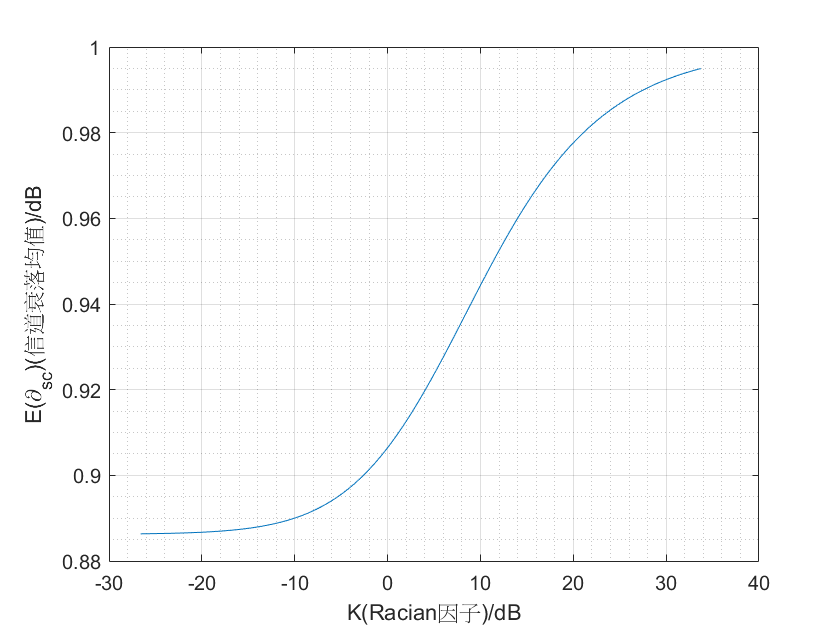

figure();
plot(20*log10(K), (average));
xlabel('K(Racian因子)/dB');
ylabel('E(\partial_{sc})(信道衰落均值)/dB');
grid on; grid minor;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%特定闪烁因子
A_E_sun=getSun(10) % 取特定的Racian因子K=10

A_E_sun = 0.9776

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算总损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_E=zeros(length(d_E),length(freq));
L_E_f=L_E_f';
for j=1:length(d_E)
   A_E(j,:)=L_E_f(j,:)+A_E_gas+A_E_g+A_E_p+A_E_sun;
end
disp('火星着陆器-火星轨道器通信链路总损耗为（dB）：');disp(A_E);

火星着陆器-火星轨道器通信链路总损耗为（dB）：
  270.7026
  275.1395
  281.1601
  284.6820
  287.1807




save('Loss_particular.mat','A_E','A_M','-mat');

function K1=getK1(f,T)  %f单位为GHz
phi=300/T;
e_0=77.66+103.3*(phi-1);
e_1=0.067*e_0;
e_2=3.52;
f_p=20.2-146*(phi-1)+316*(phi-1)^2;
f_s=39.8*f_p;

e_imag=((e_0 - e_1) / f_p) ./ (1 + (f ./ f_p).*(f ./ f_p)) + ...
    ((e_1 - e_2) / f_s) ./ (1 + (f ./ f_s).*(f ./ f_s)) ;
e_imag=e_imag.*f;
e_real= (e_0 - e_1)  ./ (1 + (f ./ f_p).*(f ./ f_p)) + ...
    (e_1 - e_2)  ./ (1 + (f ./ f_s).*(f ./ f_s)) + e_2;
K1=(0.819)./(e_imag.*(1+  ((2+e_real)./e_imag).*((2+e_real)./e_imag)   ));
K1=f.*K1;
end

function A_E_g=getA_E_g(freq,h_S,rho_w,theta2)
h_w0 = [1.6, 2.1];
r_0 = zeros(length(freq));
h_0 = 6;
r_w = zeros(length(freq));
h_w = zeros(2, length(freq));
A_E_g = zeros(2,length(freq));
for i=1:1:length(freq)
    r_0(i) = (7.19e-3+6.09./(freq(i).^2+0.227)+4.81./((freq(i)-57).^2+1.5)).*freq(i).^2*1e-3; %干燥空气下每千米的衰减值
    r_w(i) = (0.05+0.0021*rho_w+3.6./((freq(i)-22.2).^2+8.5)+10.6./((freq(i)-183.3).^2+9)+...
        8.9./((freq(i)-325.4).^2+26.3)).*freq(i).^2*rho_w*1e-4;
    h_w(:,i) = h_w0'*(1+3/((freq(i)-22.2)^2+5)+5/((freq(i)-183.3)^2+6)+...
        2.5/((freq(i)-325.4)^2+4));
    A_E_g(:,i) = (r_0(i)*h_0*exp(-h_S/h_0)+r_w(i)*h_w(:,i)')/sin(theta2*pi/180);
end
end

function [k, partial] = getKP_vh(freq, flag)
if flag==1  %水平极化
    a = [-5.33980, -0.35351, -0.23789, -0.94158];
    b = [-0.10008, 1.26970, 0.86036, 0.64552];
    c = [1.13098, 0.45400, 0.15354, 0.16817];
    mk = -0.18961;
    ck = 0.71147;
    k = 0;
    for i=1:4
        k = k+a(i)*exp(-((log10(freq)-b(i))/c(i)).^2);
    end
    k = k+mk*log10(freq)+ck;
    %%%%%%%%%%%%%%%%%%%
    a = [-0.14318, 0.29591, 0.32177, -5.37610, 16.1721];
    b = [1.82442, 0.77564, 0.63773, -0.96230, -3.29980];
    c = [-0.55187, 0.19822, 0.13164, 1.47828, 3.43990];
    mk = 0.67849;
    ck = -1.95537;
    partial = 0;
    for i=1:5
        partial = partial+a(i)*exp(-((log10(freq)-b(i))/c(i)).^2);
    end
    partial = partial+mk*log10(freq)+ck;
elseif flag==0 %垂直极化
    a = [-3.80595, -3.44965, -0.39902, 0.50167];
    b = [0.56934, -0.22911, 0.73042, 1.07319];
    c = [0.81061, 0.51059, 0.11899, 0.27195];
    mk = -0.16398;
    ck = 0.63297;
    k = 0;
    for i=1:4
        k = k+a(i)*exp(-((log10(freq)-b(i))/c(i)).^2);
    end
    k = k+mk*log10(freq)+ck;
    %%%%%%%%%%%%%%%%%%%
    a = [-0.07771, 0.56727, -0.20238, -48.2991, 48.5833];
    b = [2.33840, 0.95545, 1.14520, 0.791669, 0.791459];
    c = [-0.76284, 0.54039, 0.26809, 0.116226, 0.116479];
    mk = -0.053739;
    ck = 0.83433;
    partial = 0;
    for i=1:5
        partial = partial+a(i)*exp(-((log10(freq)-b(i))/c(i)).^2);
    end
    partial = partial+mk*log10(freq)+ck;
end
k = 10.^k;
end

function [k, partial] = getKP(freq, theta)
    [k_v, partial_v] = getKP_vh(freq, 0);
    [k_h, partial_h] = getKP_vh(freq, 1);
    tau = pi/4; %圆极化
    k = (  k_h+k_v+(k_h-k_v)*cos(theta*pi/180)*cos(theta*pi/180)*cos(2*tau)   )/2;
    partial = (  k_h.*partial_h+k_v.*partial_v+(k_h.*partial_h-k_v.*partial_v)*...
        cos(theta*pi/180)*cos(theta*pi/180)*cos(2*tau)   )/2./k;
end

function A_E_sun=getSun(K) %莱斯因子
sigma_nsc = sqrt(1/2./(K+1));   %多径信号平均功率
r = 0.01:0.01:5;    %闪烁系数的幅度
p_rice = zeros(length(K), length(r));   %闪烁系数幅度的概率分布、与闪烁指数m相关
for i=1:length(K)
    p_rice(i,:) = r/sigma_nsc(i)^2.*exp(-r.^2/2/sigma_nsc(i)^2-K(i)).*...
        besseli(0, r*sqrt(2*K(i)/sigma_nsc(i)^2));
end
average = zeros(length(K), 1);
for i=1:length(K)
    for j=1:length(r)
        average(i, 1) = average(i, 1)+p_rice(i,j)*r(j)*0.01;
    end
    average(i, 1) = average(i, 1);
end
A_E_sun=average;
end